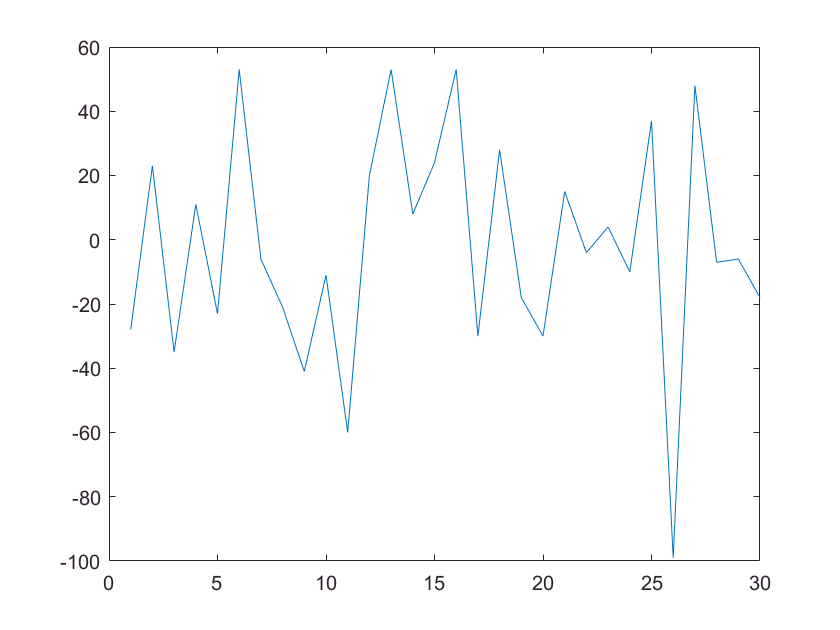

 n=30;

 %the base_sample
% rng(1);
rng(34);
 x = floor(n*randn(1,n));
 plot(x);

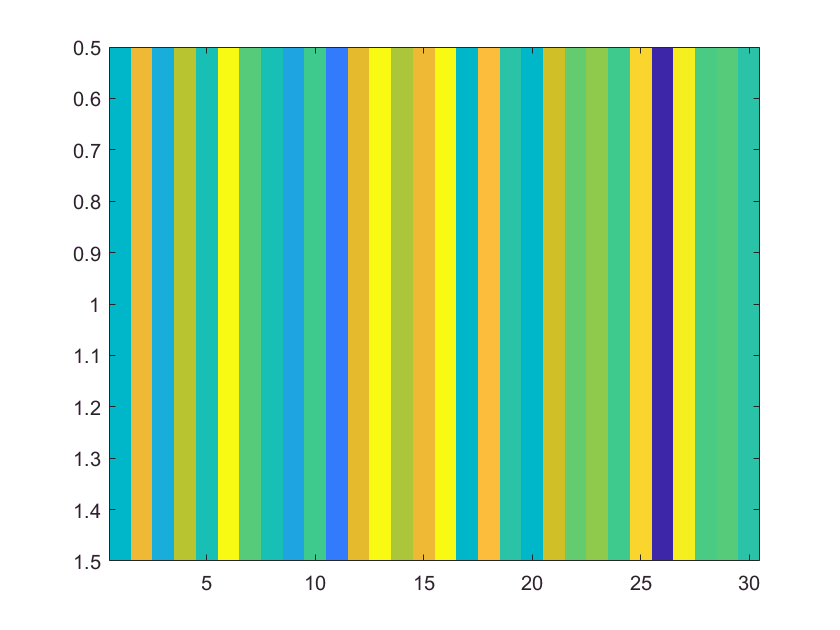

 imagesc(x)

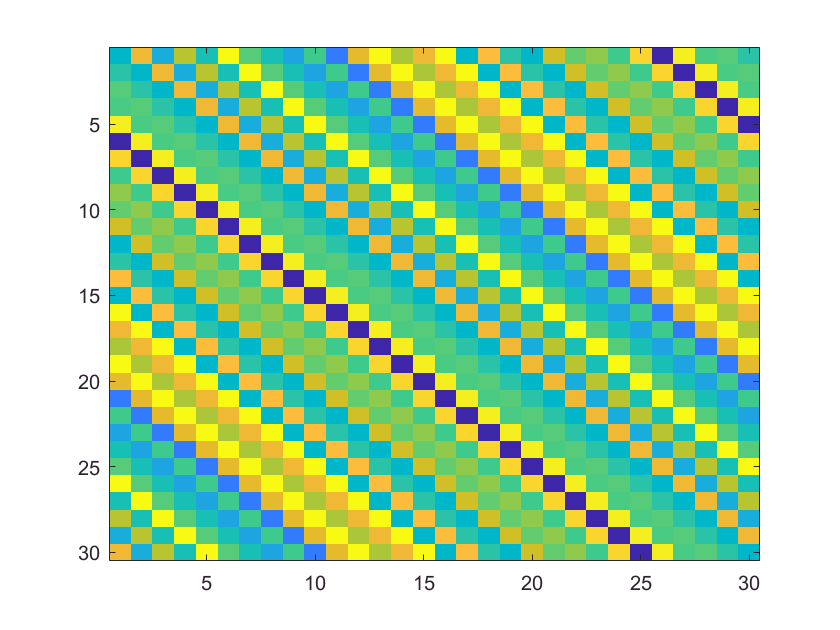

%generate circulant matrix
 X = toeplitz([x(1) fliplr(x(2:end))], x);
 imagesc(X)

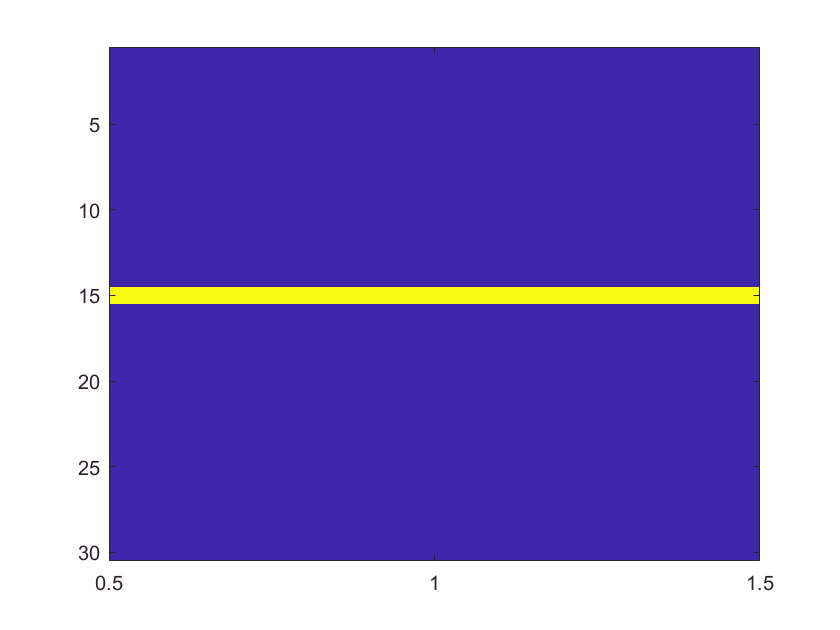

 %construct 1-d gaussian labels
 sigma = 0.1;
 y = (1:n) - floor(n/2);
 labels = exp(-0.5 / sigma^2 * y.^2);
 imagesc(labels')

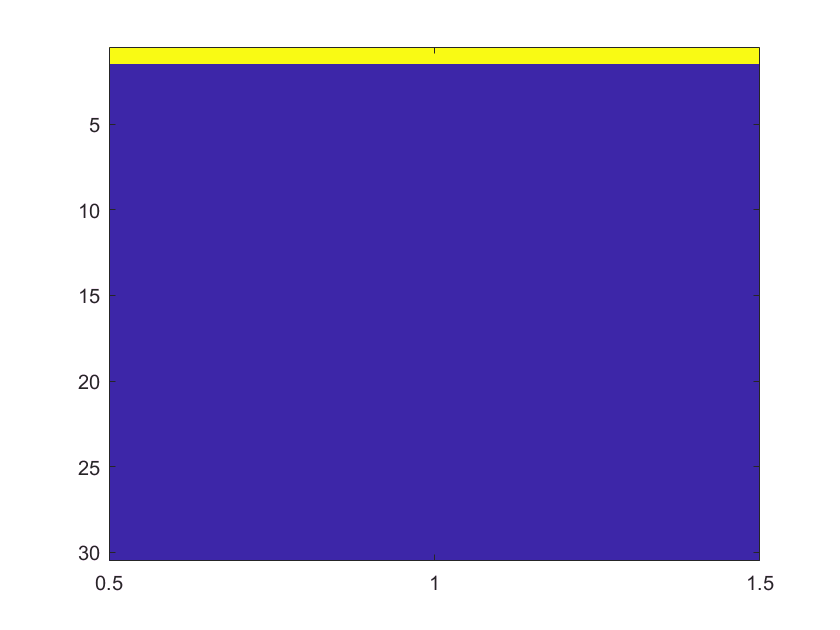


 labels =  circshift(labels, -floor(n / 2)+1 );
 imagesc(labels')

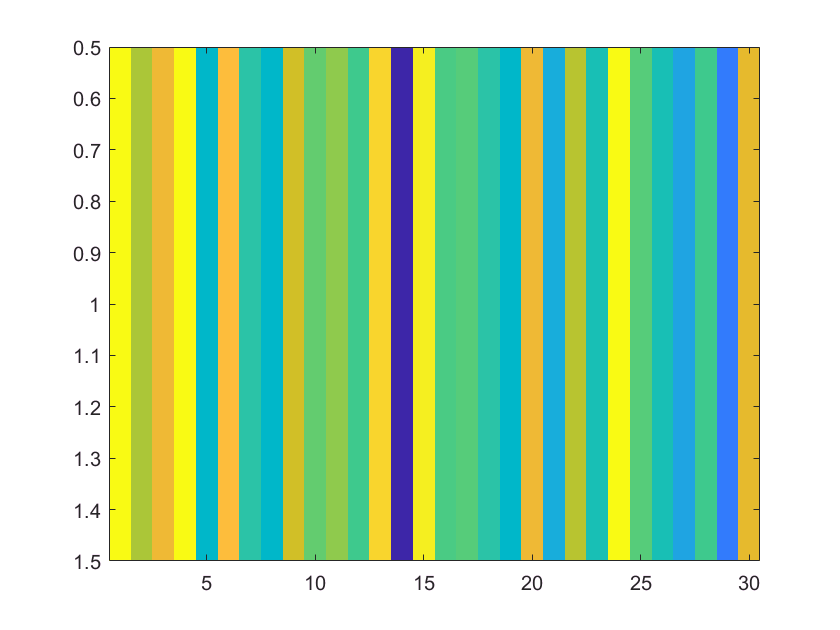

 %simulate a translated target by shift+noise
 dx = 18;
 
 % X*Q make every column of X move to the right circularly 
 Q = [zeros(n-1,1),eye(n-1);1,zeros(1,n-1)];
 z = x*Q^dx;
 imagesc(z)

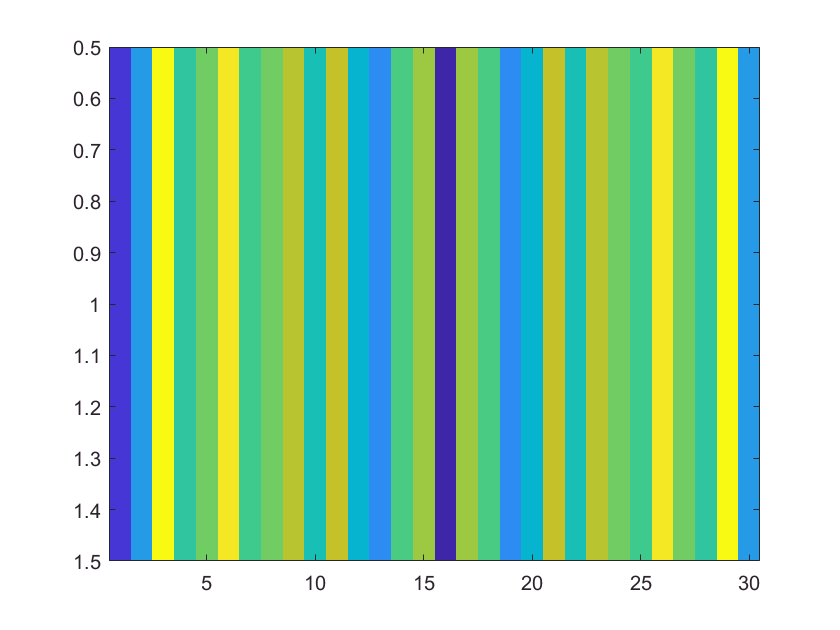

 %no kernel
 %kcf detect
 lambda = 1e-4;
 w_f = ((fft(x)).*fft(labels))./(conj(fft(x)).*fft(x)+lambda);
 imagesc(real(w_f));

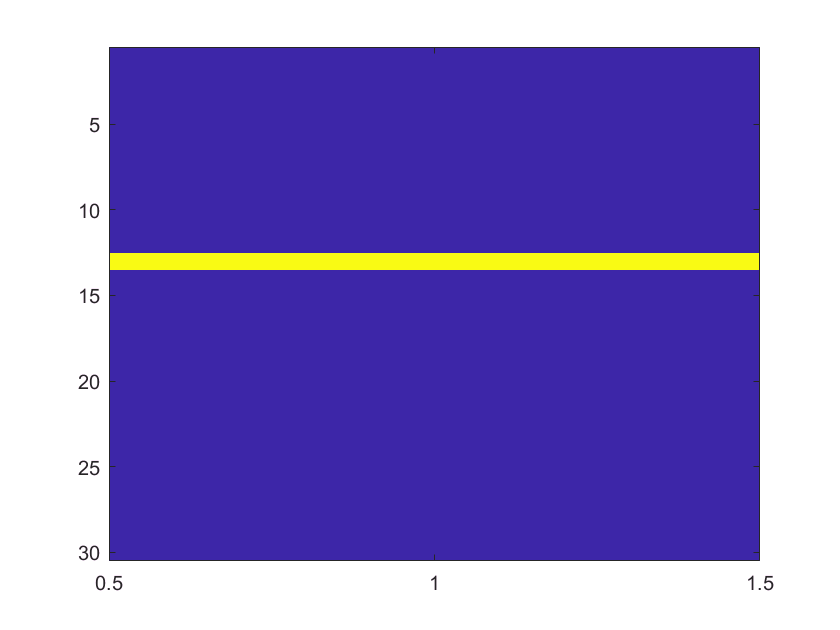

 res_f = conj(fft(z)).*w_f;
 res = real(ifft(res_f));
 imagesc(res')

 [maxValue,maxLoc]=max(res)

maxValue = 1.0000

maxLoc = 13

 loc =  n - maxLoc

loc = 17

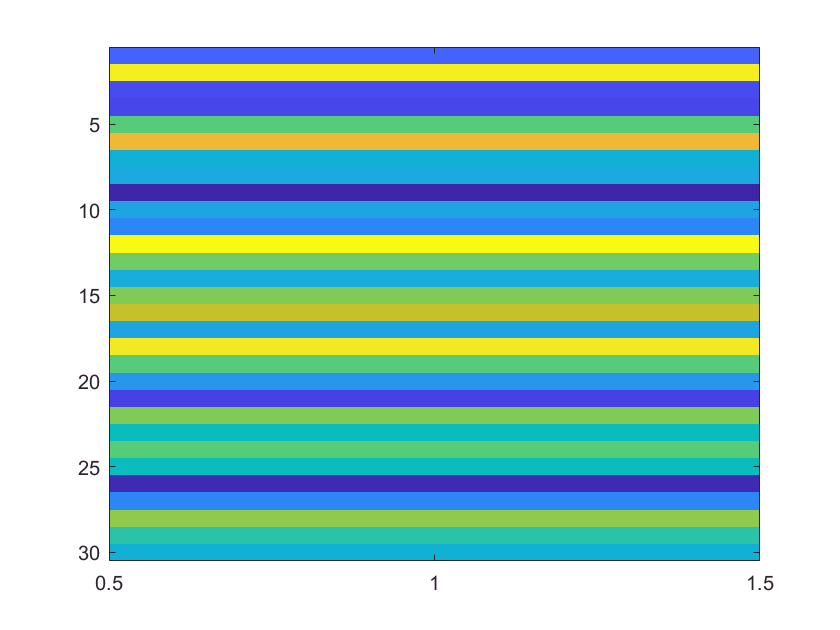

 %C(z) deduce
 ww = inv(X'*X+lambda*eye(n))*X'*labels';
 imagesc(log10(ww+1))

 a = ww - ifft(w_f.')

a =    1.0e-17 *

   -0.1301
    0.3036
    0.1735
    0.1301
         0
         0
    0.0759
    0.1735
         0
   -0.0434


 Z = toeplitz([z(1) fliplr(z(2:end))], z);
 ress = Z*(ifft(w_f.'));
 imagesc(ress)

 [maxValuee,maxLocc]=max(ress)

maxValuee = 1.0000

maxLocc = 13

 locc =  n - maxLocc

locc = 17

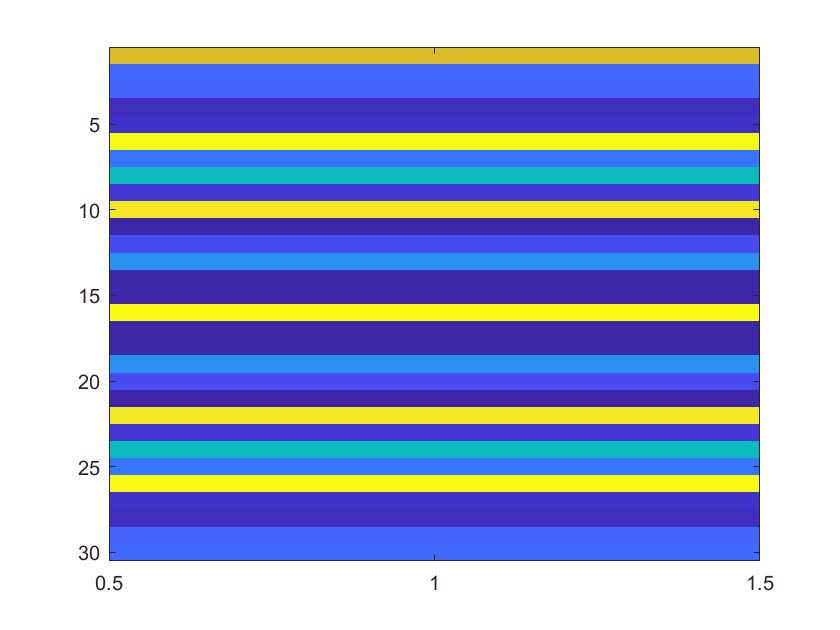

 %linear kernel can't deduce from spatial domain
 kf = fft(x) .* conj(fft(x)) / n;

 alpha_f = fft(labels)./(kf+lambda);
 imagesc(real(alpha_f.'))

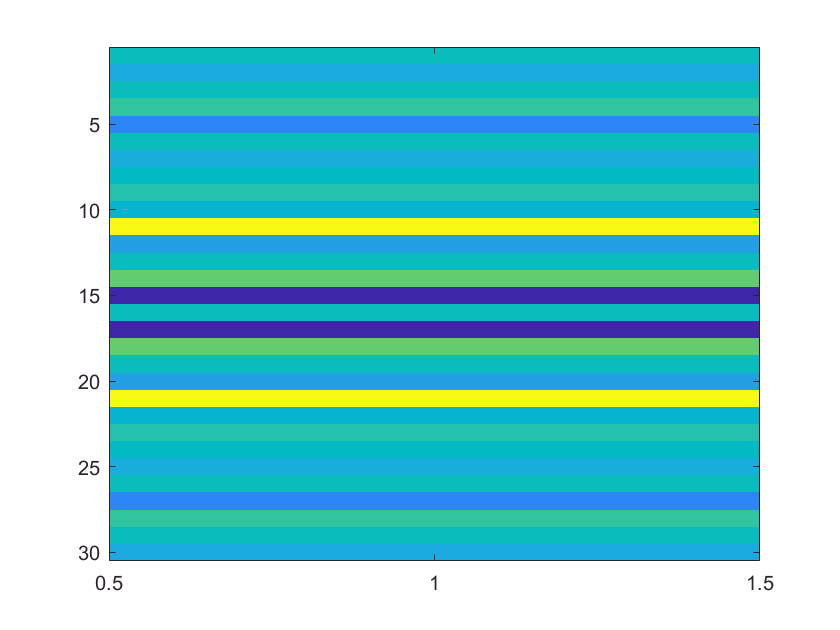

 kzf = fft(z) .* conj(fft(x)) / n;
 imagesc(real(kzf.'))

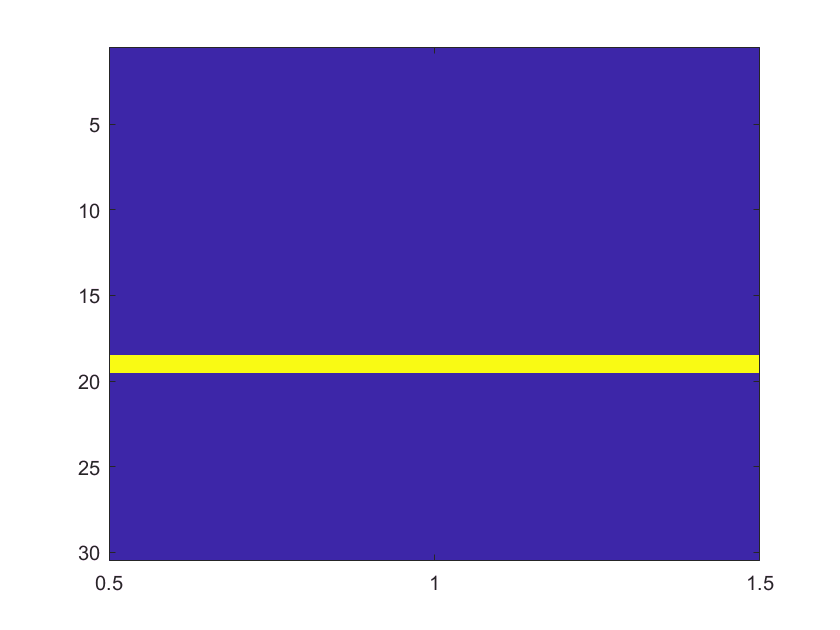

 response = real(ifft2(alpha_f .* kzf));
 imagesc(response')


 [maxValue_,maxLoc_]=max(response);
 maxLoc_

maxLoc_ = 19